clc; clear
s = settings;
s.matlab.fonts.editor.title.Style.PersonalValue = "bold";
s.matlab.fonts.editor.title.Color.PersonalValue = [255 0 0];
s.matlab.fonts.editor.normal.Size.PersonalValue = 12;
s.matlab.fonts.editor.normal.Name.PersonalValue = "Times";

# Cálculo de raíces por diversos métodos

En todos los métodos siguientes se busca resolver una ecuación del tipo:


$$f\left(x\right)=0$$


Considerando una suposición de la raíz que se esperaba determinar, siempre tomando en cuenta que se supone a las funciones como continuas y derivables.

## Método de la bisección

Se basa en el teorema de Bolsano, en el que se establece que si se tiene un ontervalo $\left\lbrack a,b\right\rbrack$ en donde $f\left(a\right)>0\;y\;f\left(b\right)<0$o viceversa, existe al menos una raíz real de la función en dicho intervalo. El proceso sigue un orden lógico como el que se muestra en la siguiente figura:

Inicio --- Introducir función "f" --- Ingresar grado de exactitud "acc"--- ingresar intervalos de z1, x2 --- evaluamos ---

clc; clear
close all
f = "5*x^3";
f = str2sym(f)

$$f = 5\,x^{3}$$

acc = 0.00001

acc = 1.0000e-05

a = -0.5

a = -0.5000

b = 0.2

b = 0.2000

fplot(f,[a - 1, b + 1])
grid on
xlabel("x")
ylabel("y")
title("Función")

fa = subs(f, a)

$$fa = -\frac{5}{8}$$

fa = double(fa)

fa = -0.6250


fb = subs(f, b)

$$fb = \frac{1}{25}$$

fb = double(fb)

fb = 0.0400


xr = (a + b) / 2

xr = -0.1500


fr = subs(f, xr)

$$fr = -\frac{27}{1600}$$

fr = double(fr)

fr = -0.0169


if (fa == 0)
    xr = a
elseif (fb == 0)
    xr = b
elseif (fa * fb > 0)
    str = "Error"
else
    while (abs(fa * fr) > acc) % abs(0 - fr) 
        if (fa * fr < 0)
            b = xr;
            
            fb = subs(f, b);
            fb = double(fb);
            
            xr = (a + b) / 2;

            fr = subs(f, xr);
            fr = double(fr);
        else
            a = xr;
            
            fa = subs(f, a);
            fa = double(fa);
            
            xr = (a + b) / 2;

            fr = subs(f, xr);
            fr = double(fr);
        end % fin del if para evaluar proceso
    end % fin del while
    xr
    fr
end %fin del if principal

xr = 0.0250

fr = 7.8125e-05

## Método de aproximaciones sucesivas

clc; clear
close all
f = "-(3/4)*x+2";
f = str2sym(f)

$$f = 2-\frac{3\,x}{4}$$

x = sym("x");
x0 = 0.9

x0 = 0.9000

acc = 0.00001

acc = 1.0000e-05

alfa = 1

alfa = 1

g = f + x

$$g = \frac{x}{4}+2$$

syms t
xRect = t;
yRect = t;
x1  = double(subs(g, x0))

x1 = 2.2250

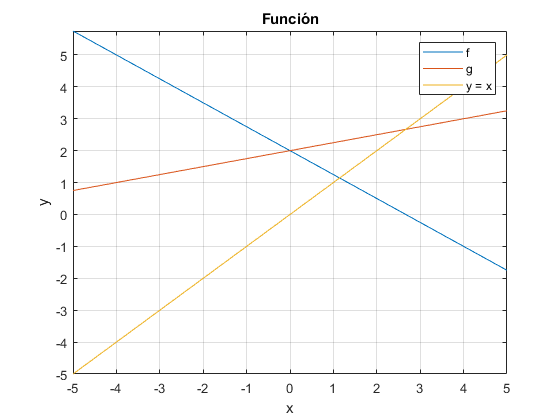

fplot(f)
hold on
fplot(g)
fplot(xRect, yRect)
% xlim([-x0 1.6*x0])
% ylim([-3*x0 1.2*x0])
grid on
xlabel("x");
ylabel("y");
legend("f", "g", "y = x")
title("Función")

hold off


c = x1 - x0;
Lim = 10000; % limite de iteraciones
k = 1; % contador
while (abs(c) > acc)
    xr = double(subs(g,x1));
    c = xr - x1;
    x1 = xr;
    k = k + 1;
    if (k == Lim)
        break
    end
end % fin de while
xr = x1

xr = 2.6667

c

c = 5.0545e-06

## Método de Newton

clc;clear
close all
f = "2*log(x)-10"; % funcion del usuario
f = str2sym(f)

$$f = 2\,\log\left(x\right)-10$$

x0 = 12 % punto muestra y precision

x0 = 12

acc = 0.00001

acc = 1.0000e-05

deri  = diff(f) % se calcula derivada asi como f y f' evaluadas

$$deri = \frac{2}{x}$$

f0 = double(subs(f, x0))

f0 = -5.0302

fprim0  = double(subs(deri, x0))

fprim0 = 0.1667

x1 = x0 - f0 / fprim0 % se define al nuevo valor iterado y su f

x1 = 42.1811

f1 = double(subs(f, x1))

f1 = -2.5161

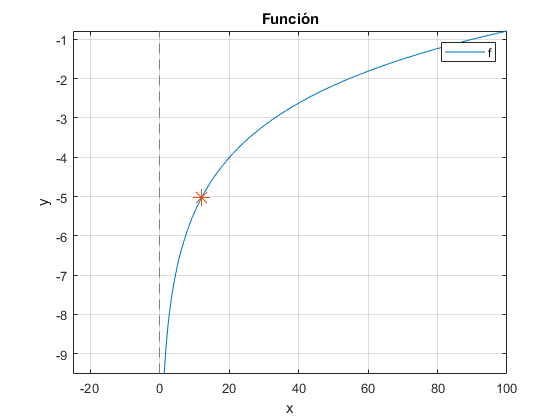

fplot(f)
hold on 
plot(x0, f0, "Marker", "*", "MarkerSize", 12)
xlim([-25 100])
grid on
xlabel("x");
ylabel("y");
legend("f")
title("Función")
hold off


Lim = 10000; % limite de iteraciones
k = 1; % contador
while (abs(f1) < acc)
    xr = x1 - double(subs(f, x1))/double(subs(deri, x1)); % se obtiene el nuevo valor
    x1 = xr;
    f1 = double(subs(f, x1));
    k = k + 1;
    if (k == Lim)
        break
    end
end % fin de while
xr = x1

xr = 42.1811

f1

f1 = -2.5161